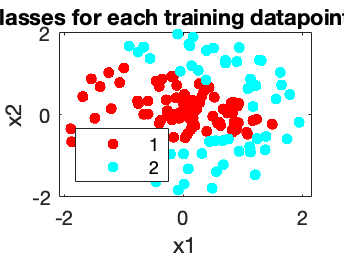

%https://www.mathworks.com/help/deeplearning/ref/patternnet.html;jsessionid=17e6dc5482df9e5be18de84c07e1
%% Load Data
load nn-test.mat
load nn-train.mat

testPoints = testData(:,1:2)';
testLabels = dummyvar(testData(:,3))';
trainPoints = trainData(:,1:2)';
trainLabels = dummyvar(trainData(:,3))';
labels = {'1','2'};
%% (a)
% Create a neural network with one hidden layer of size two
net = patternnet(2);
%set parameters of the network values
net.divideParam.trainRatio = 1;
net.divideParam.valRatio = 0;
net.divideParam.testRatio = 0;
%train the network net using the training data
net = train(net, trainPoints, trainLabels);
%picture of the trained network
view(net);
%% (b)Evaluate the model on the training dataset
%estimate the targets using the trained network
%predict activity based on neural network
scores = net(trainPoints);
%convert scores to original format for easier comparison
[~,yNum] = max(scores);
train_predLabels = yNum';
%evaluate classification
yActual = trainData(:,3);
train_accuracy = 100*nnz(yActual == train_predLabels)/length(train_predLabels);
figure
gscatter(trainPoints(1,:),trainPoints(2,:),train_predLabels)
title('Predicted Classes for each training datapoint(two neurons)')
xlabel('x1')
ylabel('x2')

fprintf('The models accuracy on the training dataset, with a hidden layer of size two, is %.2f\n',train_accuracy);

The models accuracy on the training dataset, with a hidden layer of size two, is 85.62


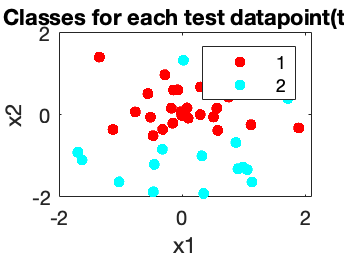

%% (c)Evaluate the model on the testing dataset
%estimate the targets using the trained network
%predict activity based on neural network
scores = net(testPoints);
%convert scores to original format for easier comparison
[~,yNum] = max(scores);
test_predLabels = yNum';
%evaluate classification
yActual = testData(:,3);
test_accuracy = 100*nnz(yActual == test_predLabels)/length(test_predLabels);
figure
gscatter(testPoints(1,:),testPoints(2,:),test_predLabels)
title('Predicted Classes for each test datapoint(two neurons)')
xlabel('x1')
ylabel('x2')

fprintf('The models accuracy on the test dataset, with a hidden layer of size two, is %.2f\n',test_accuracy);

The models accuracy on the test dataset, with a hidden layer of size two, is 85.00


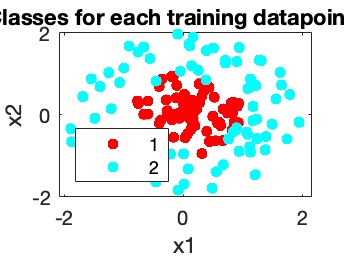

%% (d)Create a new neural network with a hidden layer size of 10
% (d)(a)Create a neural network with one hidden layer of size two
net = patternnet(10);
%set parameters of the network values
net.divideParam.trainRatio = 1;
net.divideParam.valRatio = 0;
net.divideParam.testRatio = 0;
%train the network net using the training data
net = train(net, trainPoints, trainLabels);
%picture of the trained network
view(net);
%% (d)(b)Evaluate the model on the training dataset
%estimate the targets using the trained network
%predict activity based on neural network
scores = net(trainPoints);
%convert scores to original format for easier comparison
[~,yNum] = max(scores);
train_predLabels = yNum';
%evaluate classification
yActual = trainData(:,3);
train_accuracy = 100*nnz(yActual == train_predLabels)/length(train_predLabels);
figure
gscatter(trainPoints(1,:),trainPoints(2,:),train_predLabels)
title('Predicted Classes for each training datapoint(ten neurons)')
xlabel('x1')
ylabel('x2')

fprintf('The models accuracy on the training dataset, with a hidden layer of size ten, is %.2f\n',train_accuracy);

The models accuracy on the training dataset, with a hidden layer of size ten, is 99.38


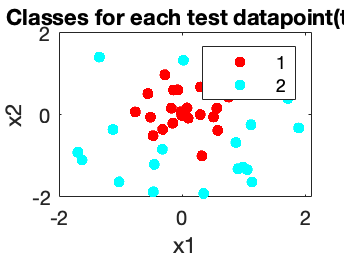

%% (d)(c)Evaluate the model on the testing dataset
%estimate the targets using the trained network
%predict activity based on neural network
scores = net(testPoints);
%convert scores to original format for easier comparison
[~,yNum] = max(scores);
test_predLabels = yNum';
%evaluate classification
yActual = testData(:,3);
test_accuracy = 100*nnz(yActual == test_predLabels)/length(test_predLabels);
figure
gscatter(testPoints(1,:),testPoints(2,:),test_predLabels)
title('Predicted Classes for each test datapoint(ten neurons)')
xlabel('x1')
ylabel('x2')

fprintf('The models accuracy on the test dataset, with a hidden layer of size ten, is %.2f\n',test_accuracy);

The models accuracy on the test dataset, with a hidden layer of size ten, is 92.50
